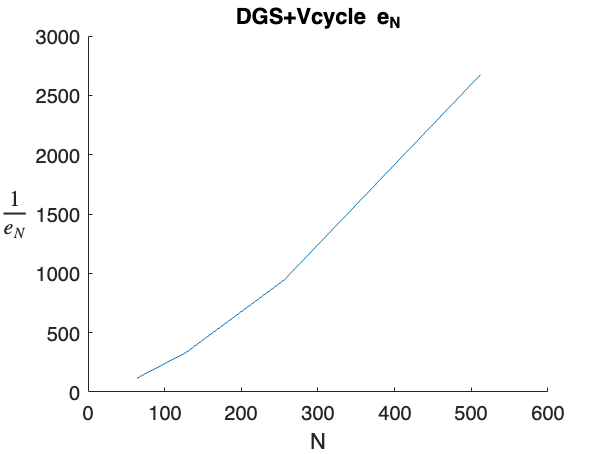

Nset = [64; 128; 256; 512];
err = zeros(length(Nset), 1);
t = zeros(length(Nset), 1);
for i = 1: length(Nset)
    tic;
    N = Nset(i);
    para = get_para(N);
    poi = Vcycle_DGS(para);
    err(i) = err_std(poi, para);
    t(i) = toc;
end
figure;
hold on;
plot(Nset, 1./err);
title("DGS+Vcycle e_N");
xlabel("N");
ylabel("$\frac{1}{e_N}$", ...
    'interpreter', 'latex', ...
    "Rotation",0);
hold off;

Names = {'N'; 'time'; 'e_N'}

Names = 3×1 cell array
    {'N'   }
    {'time'}
    {'e_N' }


T = table(Nset, t, err, ...
    'VariableNames',Names)

T = 4×3 table
     N       time         e_N    
    ___    ________    __________

     64    0.029333     0.0085233
    128     0.11581     0.0030007
    256     0.54628     0.0010587
    512      2.3222    0.00037395


Nset = [64, 128, 256, 512];
err = zeros(length(Nset), 1);
t = zeros(length(Nset), 1);
for i = 1: length(Nset)
    tic;
    N = Nset(i);
    para = get_para(N);
    poi = UIM(para);
    err(i) = err_std(poi, para);
    t(i) = toc;
end

T = 55

T = 105

T = 39

T = 79

figure;
hold on;
plot(Nset, 1./err);
title("Uzawa Iteration Method e_N");
xlabel("N");
ylabel("$\frac{1}{e_N}$", ...
    'interpreter', 'latex', ...
    "Rotation",0);
hold off;

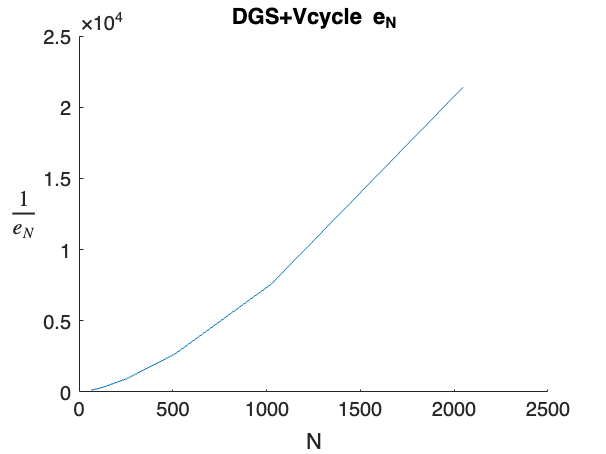

figure;
hold on;
plot(Nset, 1./err);
title("Uzawa Iteration Method e_N");
xlabel("N");
ylabel("$\frac{1}{e_N}$", ...
    'interpreter', 'latex', ...
    "Rotation",0);
hold off;

tic;
N = 1024;
para = get_para(N);
poi = IUIM(para);

nr = 467.5102

err_std(poi, para)
t = toc

N = 64;
para = get_para(N);
find_eig(para)

ans = 1.0000

% A = [-0.8944, -0.4472;
%     0, 0];
% res.f = A;
% res.g = zeros(N);
% a=CG(poi, res, para);